## **Problem 4)**

**a)**

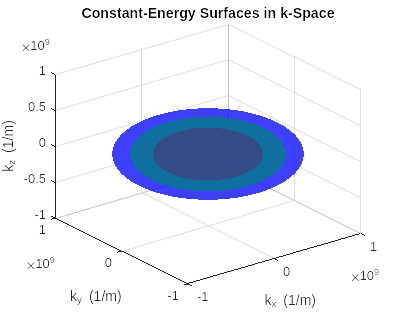

% Constants
hbar = 1.0545718e-34;  % Reduced Planck's constant (J·s)
m0 = 9.10938356e-31;   % Free electron mass (kg)
m_xy = 0.98 * m0;      % Effective mass in xy-plane
m_z = 0.19 * m0;       % Effective mass in z-direction
q = 1.6e-19; 

% Energy values to plot (in eV)
E_values = [0.01, 0.02, 0.03] * q;

% k-space range
k_max = 1e9;  % Maximum k value in 1/m
k_points = 50; % Grid points in each direction
[kx, ky, kz] = meshgrid(linspace(-k_max, k_max, k_points), ...
                         linspace(-k_max, k_max, k_points), ...
                         linspace(-k_max, k_max, k_points));

% Energy dispersion equation
E_k = (hbar^2 / (2 * m_xy)) * (kx.^2 + ky.^2) + (hbar^2 / (2 * m_z)) * kz.^2;

% Plot constant-energy surfaces
figure('Position', [100, 100, 1000, 800]); % Increase figure window size
hold on;
colors = ['r', 'g', 'b'];

for i = 1:length(E_values)
    E_level = E_values(i);
    fv = isosurface(kx, ky, kz, E_k, E_level);
    p = patch(fv);
    set(p, 'FaceColor', colors(i), 'EdgeColor', 'none', 'FaceAlpha', 0.5);
end

% Plot settings
xlabel('k_x (1/m)');
ylabel('k_y (1/m)');
zlabel('k_z (1/m)');
zlim([-1e9 1e9]);
title('Constant-Energy Surfaces in k-Space');
grid on;
view(3);
hold off;

My intution says this isn't entirely correct, because if the effective mass for the z-component is lower, then the slope of its k-component should be steeper. This ellipse stretches towards kx and ky, giving it a greater slope. I honestly can't get this to change though.

**b) **

This is currently an ellipse, very close to a sphere, so if we can get all k components to have equal weights, a sphere is obtainable. Lets get kz to have the same weight at kx and ky, by setting a new coordinate system. We just need to use the ratio between the two effective masses to get all the k's to equal, and k in the z direction is (supposed to) be steeper, so lets shrink this to kx and ky. Our new kz' is $=\sqrt{\frac{m_z }{m_{\textrm{xy}} }}*k_z$. Now this is like any previous 3D DOS derivition, with the final answer being $g\left(E\right)=\frac{1}{4\pi^2 }{\left(\frac{2m}{h^2 }\right)}^{1\ldotp 5} \sqrt{E}$, BUT, our new m is equal to m_xy, and the new E is proportional to ${{k^{\prime } }_x }^2 +{{k^{\prime } }_y }^2 +{{k^{\prime } }_z }^2$, while k'_z has the effective mass ratio discussed early.

**c)**

Our new quantized k would be $k_z =\frac{\pi n}{W}$, so we just have a new equation of $E=\frac{h^2 }{2m_{\textrm{xy}} }\left({k_x }^2 +{k_y }^2 \right)+\frac{h^2 }{2m_z }{\left(\frac{n\pi }{W}\right)}^2$

**d)**

Same as in problem c) but we'll skip to


$$E=\frac{h^2 }{2m_{\textrm{xy}} }\left({k_x }^2 +{\frac{n\pi }{W}}^2 \right)+\frac{h^2 }{2m_z }{k_z }^2$$


OR


$$E=\frac{h^2 }{2m_{\textrm{xy}} }\left({k_y }^2 +{\frac{n\pi }{W}}^2 \right)+\frac{h^2 }{2m_z }{k_z }^2$$


**e)**

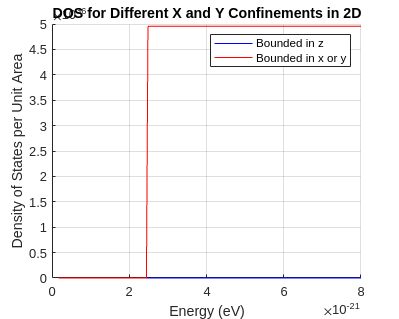

% Constants
hbar = 1.0545718e-34; 
m0 = 9.10938356e-31;  
m_xy = 0.98 * m0;     
m_z = 0.19 * m0;     
W = 5e-9;  % Quantum well width (5 nm)

% Energy range in eV
E_range = linspace(0.001, 0.05, 200) * q; 

% 2D confinement in z-direction (case c)
g_2D_z = zeros(size(E_range));
for n = 1:5  
    E_n = (hbar^2 / (2 * m_z)) * (n * pi / W) ^ 2; 
    g_2D_z = g_2D_z + ((2 * m_xy) / (2 * pi * hbar^2)) .* (E_range >= E_n);
end

% 2D confinement in x or y-direction (case d)
g_2D_x = zeros(size(E_range));
for n = 1:5  
    E_n = (hbar^2 / (2 * m_xy)) * (n * pi / W) ^ 2; 
    g_2D_x = g_2D_x + ((2 * m_z) / (2 * pi * hbar^2)) .* (E_range >= E_n);
end

figure('Position', [100, 100, 1000, 800]); % Increase figure window size
hold on;
plot(E_range, g_2D_z, 'b');
plot(E_range, g_2D_x, 'r');
xlabel('Energy (eV)');
ylabel('Density of States per Unit Area');
title('DOS for Different X and Y Confinements in 2D');
legend('Bounded in z', 'Bounded in x or y');
grid on;
hold off;

This is like problem 3) when we experienced a step function when a 3D system is confined in one dimension. As we calculated in part b) of this problem, the 3D DOS depends on the effective mass, so the step function of the density of states will depend on which dimension we bound the electron in, because its effective mass in the dimension will change the DOS.